# IMVIEW Image Display Function

The MATLAB function `imview` displays a binary, grayscale, indexed, or RGB image. It is intended to be used instead of `imshow` in most cases. It behaves better with other MATLAB graphics functions, it uses a higher quality image interpolation, and it displays and makes it easy to change the zoom level.

## System Requirements

The function `imview` requires MATLAB R2022b or later.

For displaying an image using a spatial reference ([`imref2d`](https://www.mathworks.com/help/images/ref/imref2d.html)), Image Processing Toolbox is required.

## Examples

### Display Truecolor Image

A = imread("capitol-building-stained-glass.jpg");
whos A

  Name         Size                   Bytes  Class    Attributes

  A         2662x3550x3            28350300  uint8              



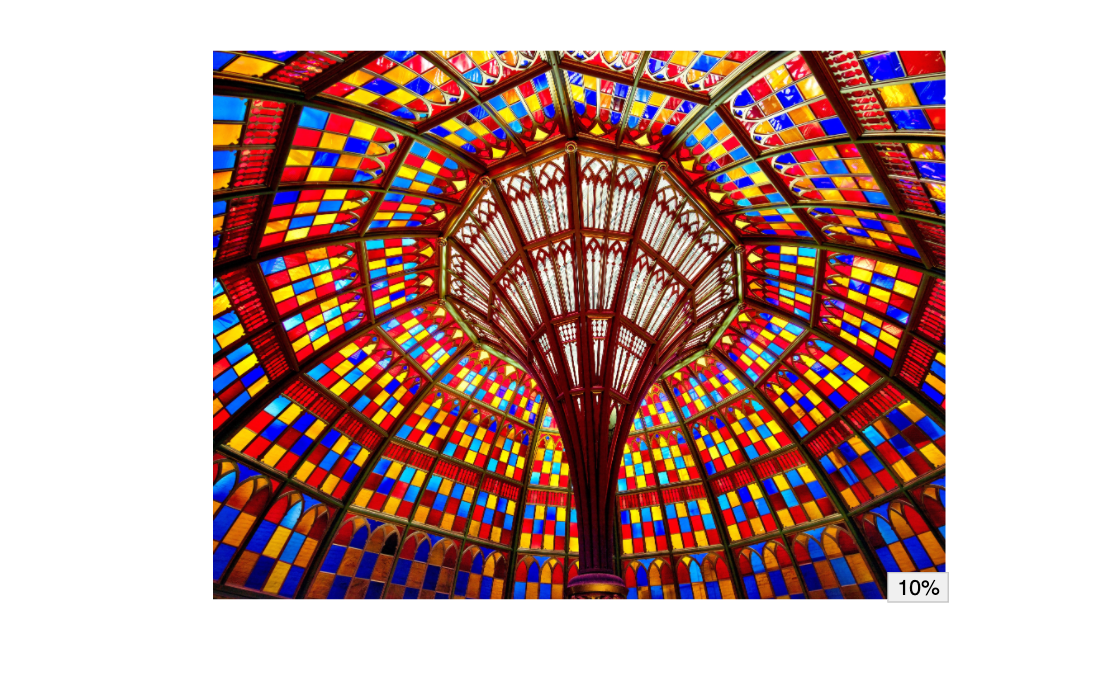

imview(A)

### Display Grayscale Image

B = imread("margaret-d-foster.jpg");
whos B

  Name         Size                 Bytes  Class    Attributes

  B         4181x5154            21548874  uint8              



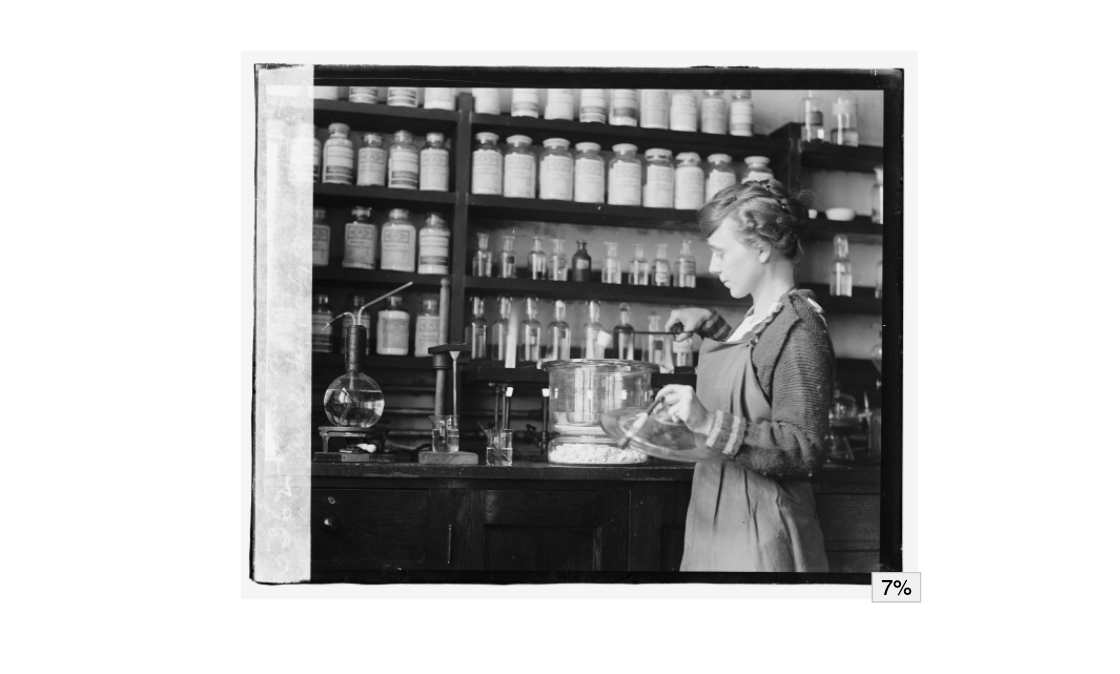

imview(B)

### Display Binary Image

C = imread("US2484408-drawings-page-1-cropped.png");
whos C

  Name         Size                Bytes  Class    Attributes

  C         1086x1801            1955886  uint8              



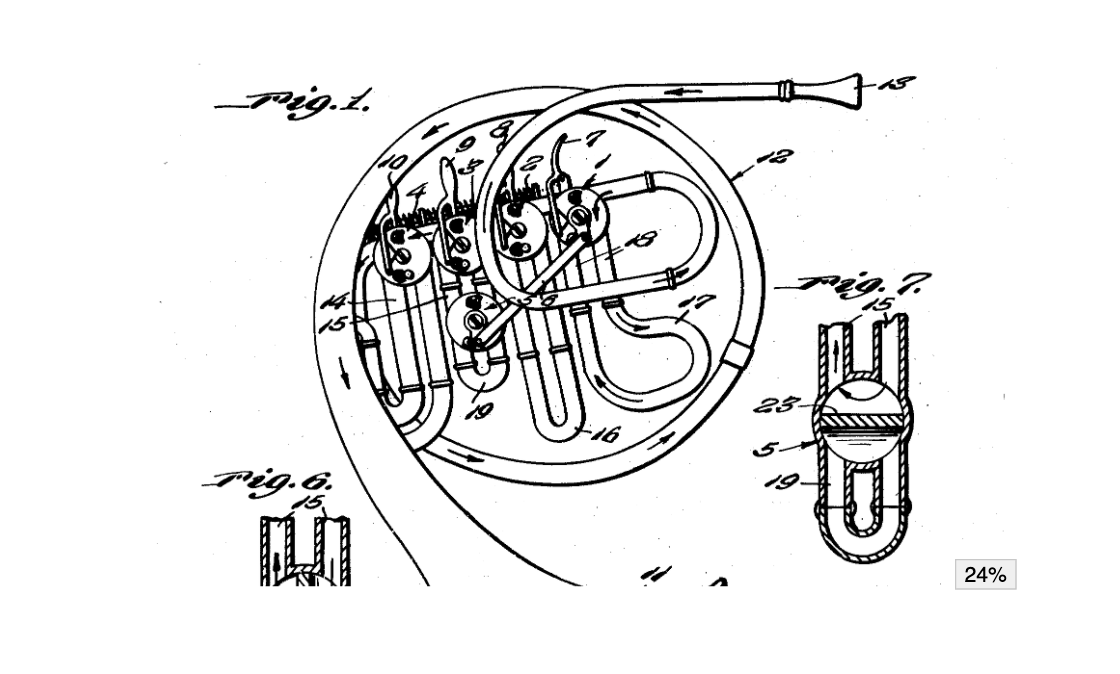

imview(C)

### Display Indexed Image

[X,map] = imread("trees.tif");
whos X map

  Name        Size             Bytes  Class     Attributes

  X         258x350            90300  uint8               
  map       256x3               6144  double              



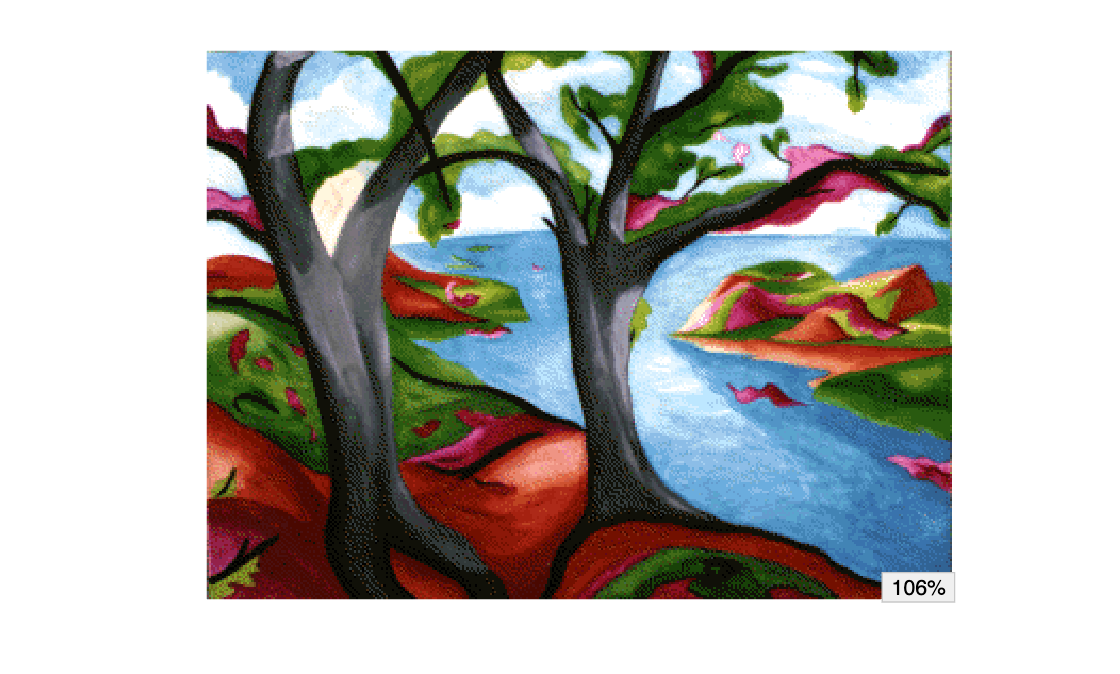

imview(X,map)

### Set the Zoom Level Directly Using the Zoom Level Display

imview(X,map)

Click on the zoom level display at the lower right and then change it to a different zoom level.

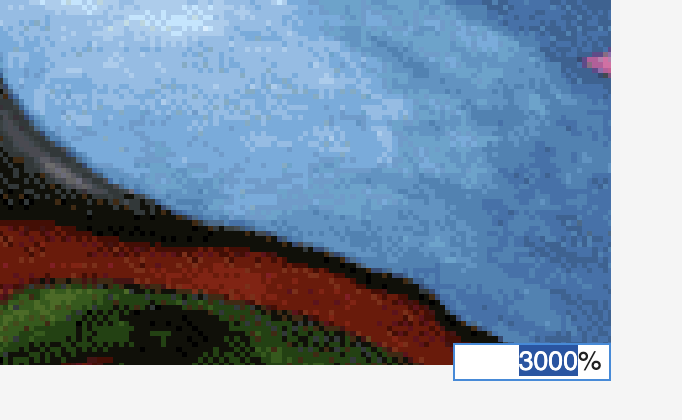

Here is the resulting image at 3000% zoom:

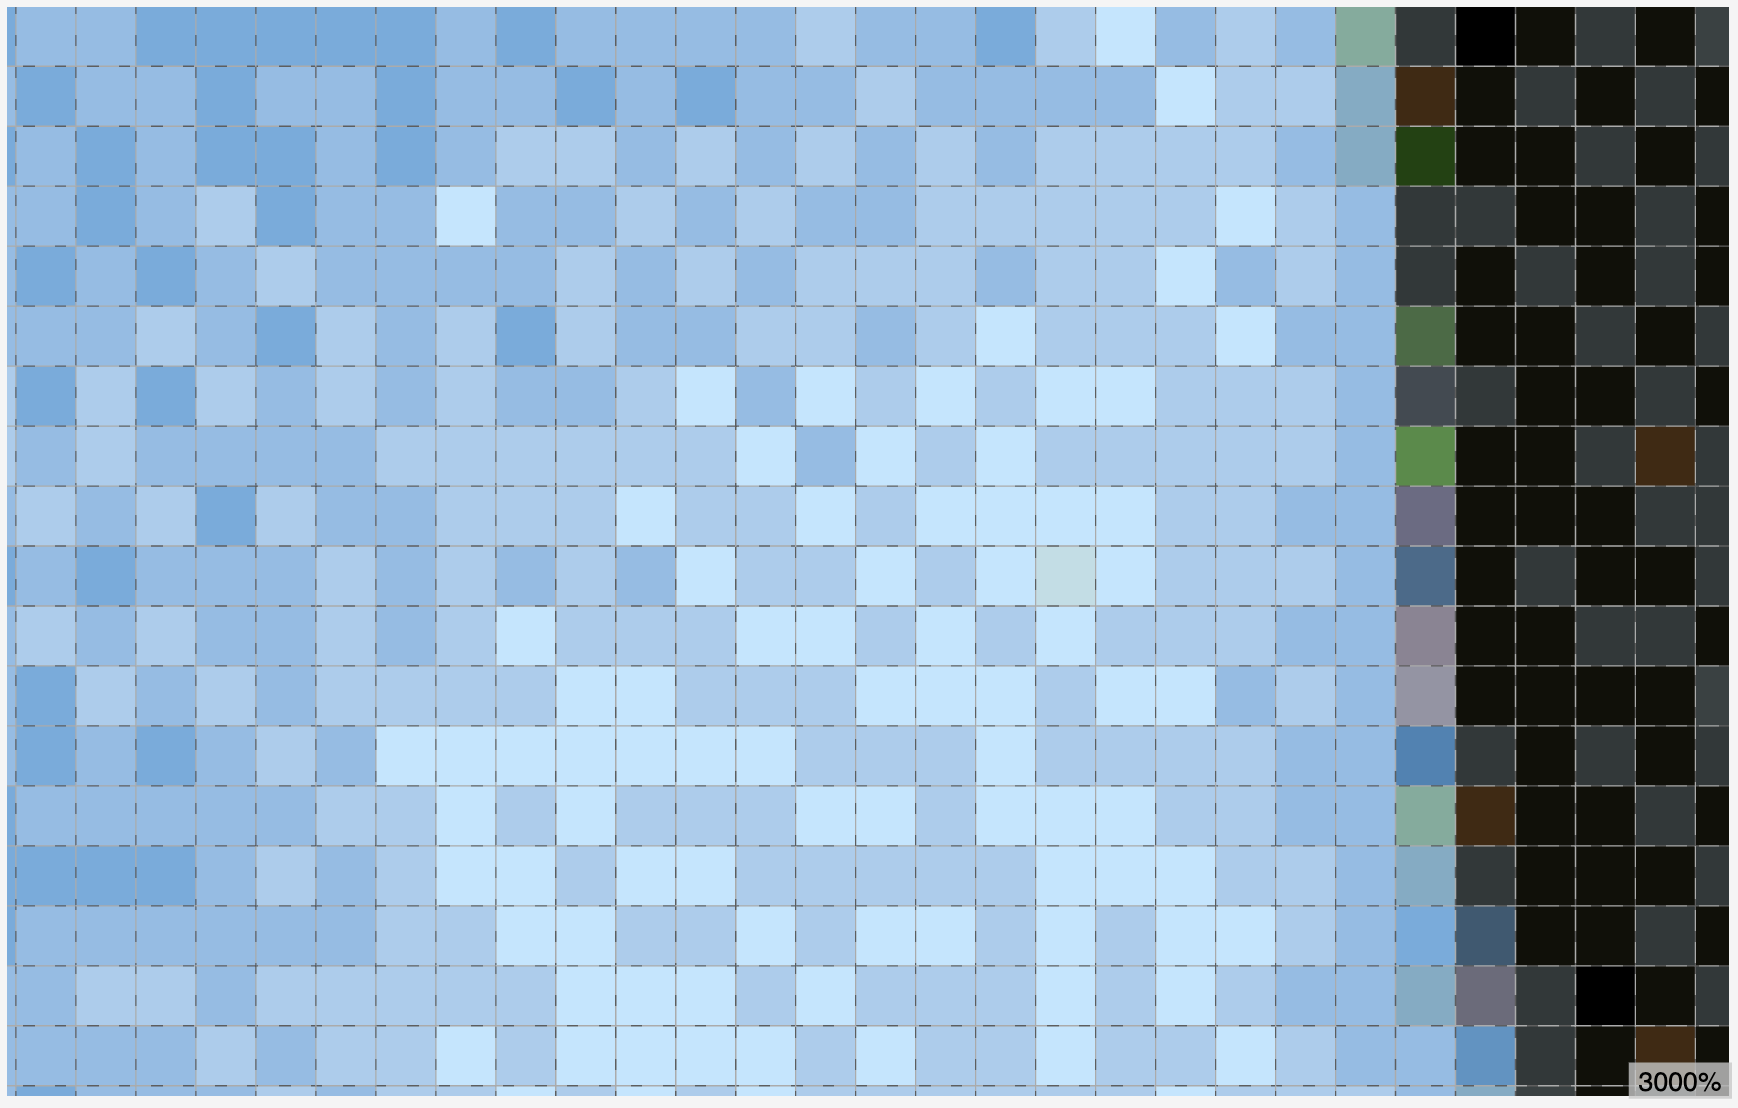

### Use Axes Toolbar Button to Show or Hide Zoom Level

Click on the button with the "%" icon to show or hide the zoom level.

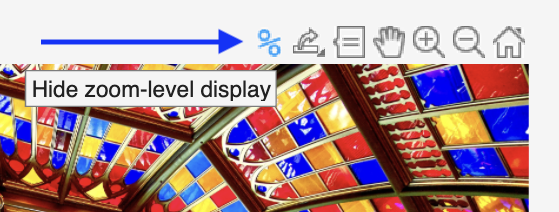

### Use Named Argument to Show or Hide Zoom Level

### See Pixel Grid Automatically at Extreme Zoom Levels

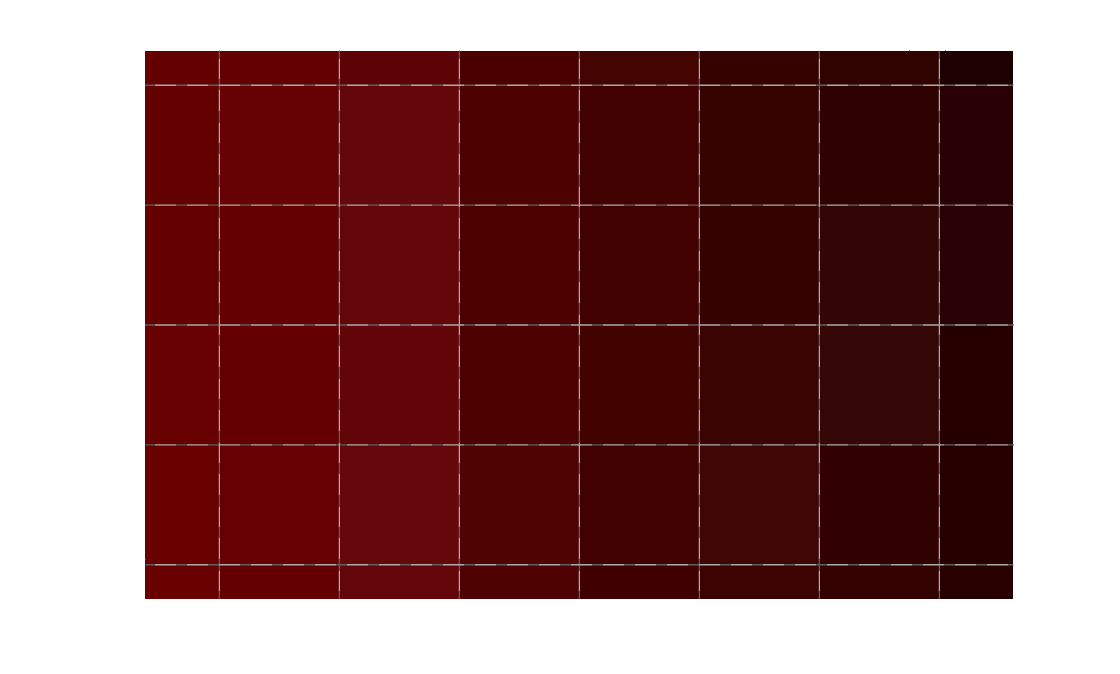

imview(A)
setImageZoomLevel(6000)

### Zoom Image to Full Size of Plot Region

When zooming into a skinny wide or skinny tall image, `imview` makes full use of the plot region, unlike `imshow`.

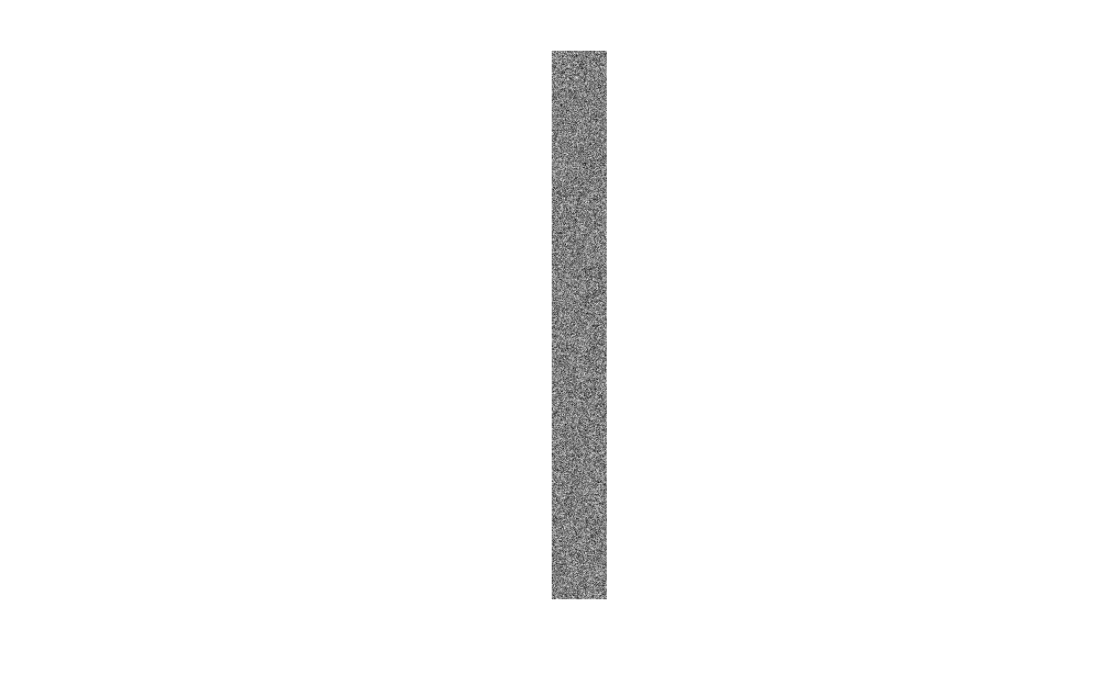

A = rand(1000,100);
imview(A)

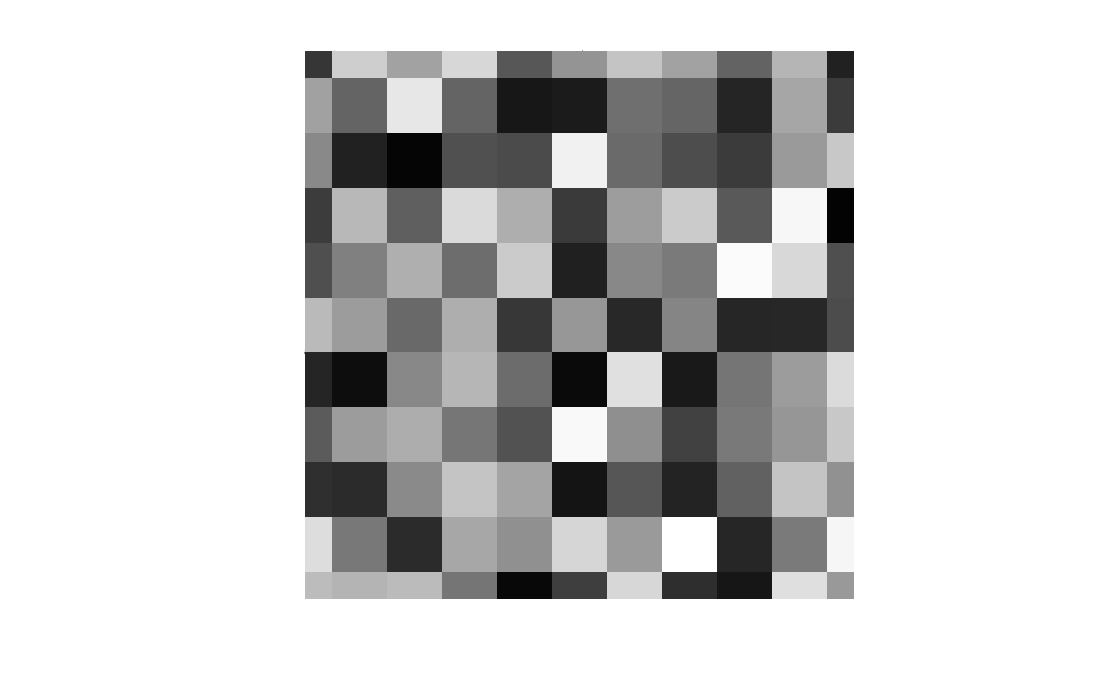

axis([50 60 500 510])

### Set the Gray Limits Manually

The dataset in this example is 1-month rainfall for December 2024, 0.5 degree resolution, IMERG program, downloaded from [https://neo.gsfc.nasa.gov/view.php?datasetId=GPM_3IMERGM](https://neo.gsfc.nasa.gov/view.php?datasetId=GPM_3IMERGM) on 25-Jan-2025. The colormap is the same colormap used on that web page. The data is in millimeters, and the color scale is intended to from 1 to 2000 mm.

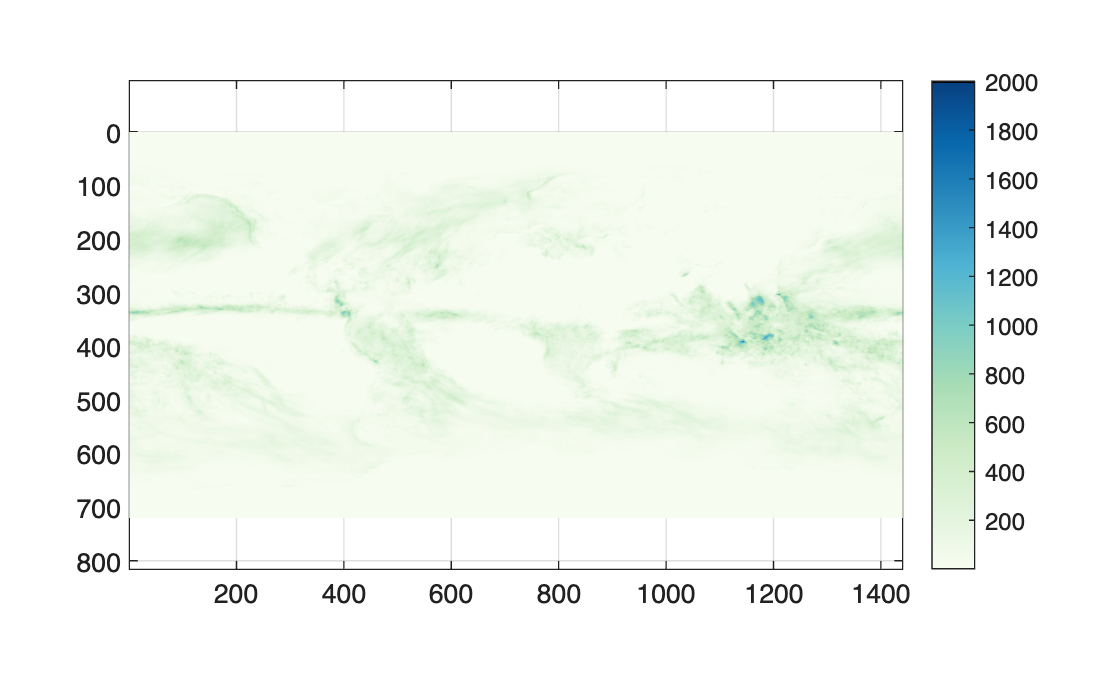

load nasa-rainfall-05-degrees-dec-2024 R map
imview(R,GrayLimits=[1 2000])
colormap(map)
axis on
box on
colorbar

### Set the Gray Limits to the Full Data Range

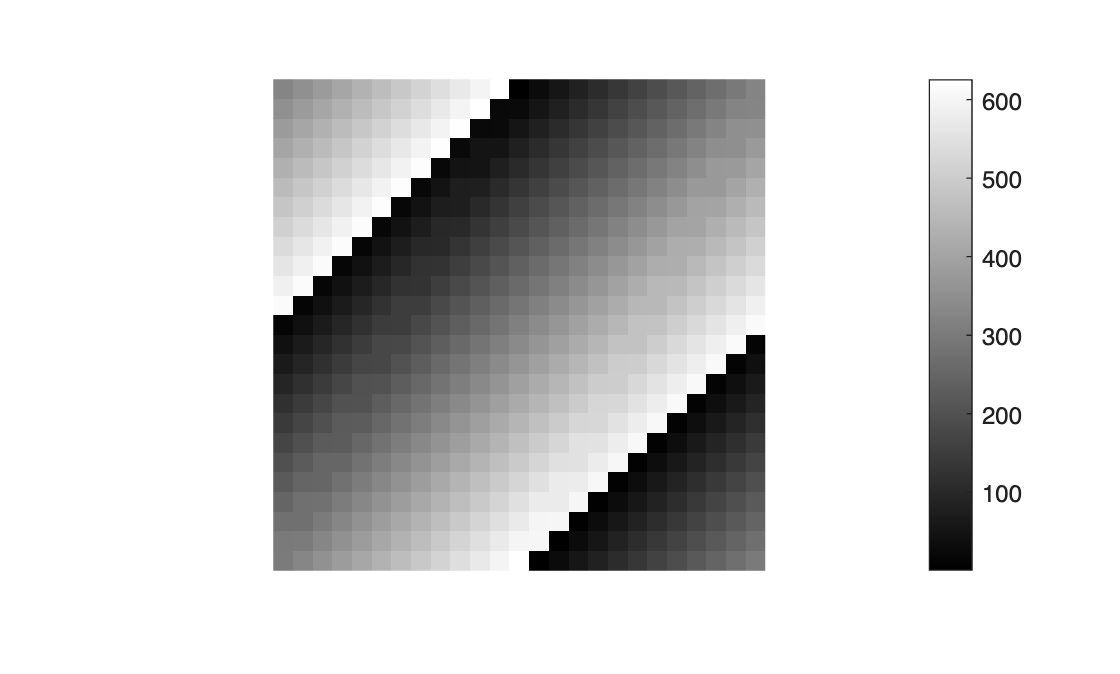

D = magic(25);
imview(D, GrayLimits="datarange", Interpolation="nearest")
colorbar

### Display Image Using a Spatial Reference

*This example requires Image Processing Toolbox. The task can also be accomplished without the Image Processing Toolbox by setting the *`XData`* and *`YData`* properties of the image.*

Display an image so that each pixel is 0.001 x 0.001 in the *x-y* domain. Zoom into the center of the image. Turn the axes display on so that the x and y tick labels are visible.

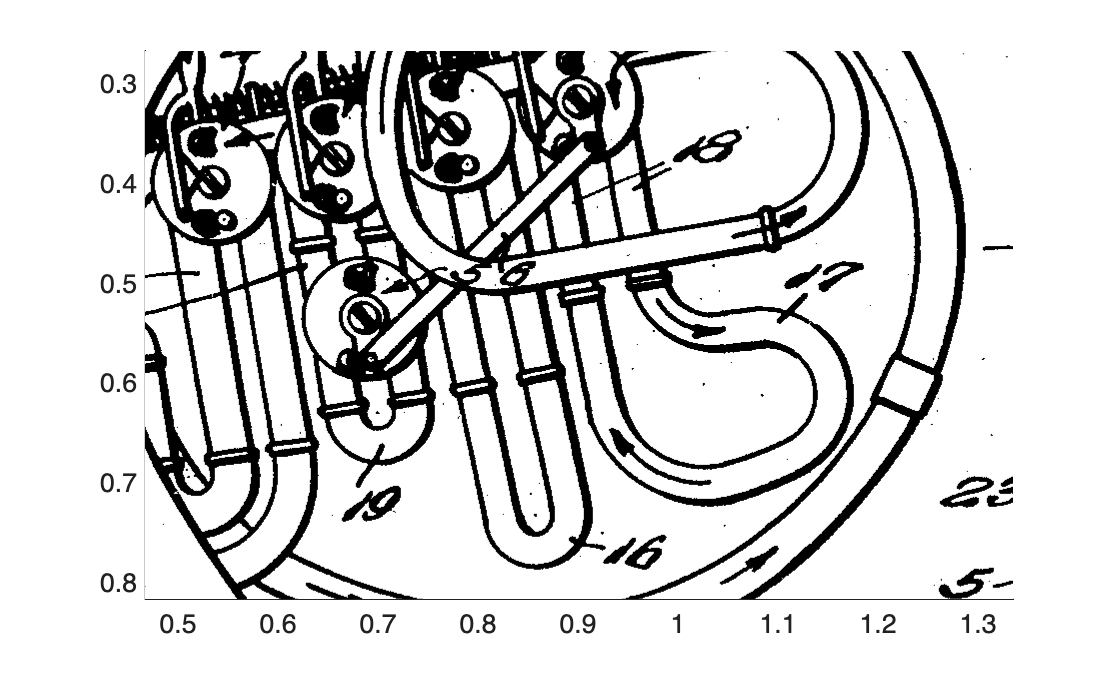

ref = imref2d(size(C),0.001,0.001);
imview(C, SpatialReference = ref)
setImageZoomLevel(50)
axis on

### Display Image with Visible Axes

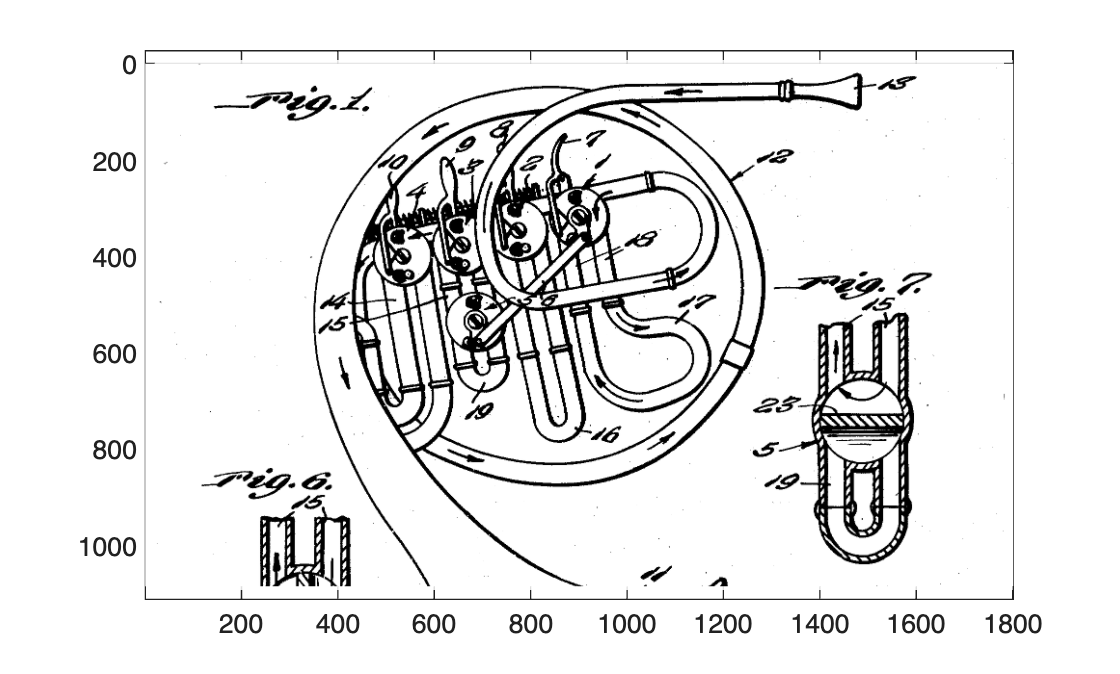

imview(C)
axis on
box on

### Display Image and Plot New Data

Unlike `imshow`, the function `imview` does not prevent the axes object from automatically readjusting its limits to respond to additional plotted data. The axes does, however, continue to maintain a data aspect ratio of `[1 1 1]`.

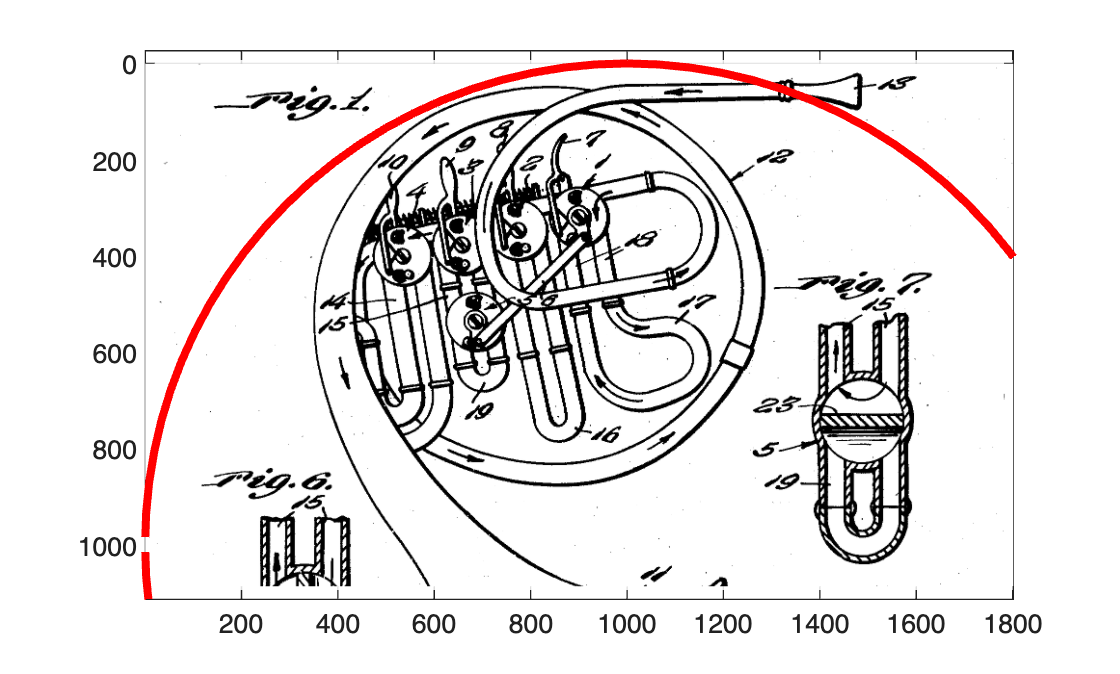

imview(C)
hold on
rectangle(Position = [0 0 2000 2000],...
    Curvature = [1 1],...
    EdgeColor = "red",...
    LineWidth = 3);
hold off
axis on
box on

### Change IMVIEW Settings

The function `imview` has several settings that can be used to modify some of its behavior. shows or hides the zoom level display by default is controlled by a setting. Use the settings interface to programmatically change this setting. You can make the change temporary, or you can make it persist from one MATLAB session to another.

The `ShowZoomLevel` setting controls whether `imview` displays the current zoom level at the lower right of the image by default. The zoom-level display can also be shown and hidden using a button in the axes interaction toolbar.

The `AdaptiveInterpolationThreshold` setting is the approximate pixel size, in inches, when the interpolation switches automatically from bilinear to nearest neighbor.

The `PixelGridThreshold` setting is the approximate pixel size, in inches, when a faint grid will be shown along the pixel edges.

View `imview` settings:

s = settings;
s.imview

Make a temporary change to a setting:

Make a persistent change to a setting:

## Comparison with IMSHOW

The function `imview` differs from `imshow` in several important ways:

- `imview` does not resize the figure containing the image display. Instead, the image is displayed in the current axes in the current figure.

- `imview` displays the image using bilinear interpolation and antialiasing, unless individual pixels are larger than about 0.25 inches. In that case, the interpolation switches automatically to nearest neighbor, and a pixel grid is shown. The function `imshow` uses nearest neighbor interpolation, without antialiasing, by default.

- `imview` displays the current zoom level at the lower right of the image. The zoom level can be changed directly by clicking on the zoom level display and editing it. There are several ways to turn off this display if desired.

- Unlike `imshow`, `imview` does not explicitly set the axes `XLim` and `YLim` properties. Instead, it sets the `XLimitMethod` and `YLimitMethod` properties to `"tight"`. With this choice, the axes limits will tightly enclose the data contained by the axes, including the image and anything else that might also be plotted in the same axes. Also unlike `imshow`, the axes limits will continue to automatically adjust to additional data being plotted there.

- When displaying an indexed image, `imview` sets the colormap of the axes instead of the figure.

- `imview` supports `AlphaData` input.

- When reading image data from a PNG file, `imview` will read and use pixel transparency data if it is in the file.

- `imview` does not have an input argument for controlling the initial zoom level, as `InitialMagnification` does for `imshow`. Instead, call `setImageZoomLevel` or `zoomImage` after calling `imview`.

- `imview` does not observe the MATLAB Image Display Preferences.

## Limitations

When using a PNG file's pixel transparency, `imview` does not read or use the background color contained in the file, so the appearance may be different from the PNG creator's intent.

## Installation and Setup

Download the `.mltbx` file from the [GitHub repository releases area](https://github.com/eddins/imview/releases/)%20or%20from%20the%20[File%20Exchange). Double-click on the downloaded file to automatically and run the MATLAB add-on installer. This will copy the files to your MATLAB add-ons area and add the appropriate folder to your MATLAB search path.

In MATLAB releases prior to R2026a, this `imview` function may be shadowed by a placeholder function in Image Processing Toolbox with the same name. That function only issues an error message. It is a remnant of a general image display tool that existed in the product about 20 years ago. To fix this installation issue:

- Click "Set Path" in the MATLAB toolstrip. 

- Find the path entry for the IMVIEW add-on; it may be near the bottom of the long list. 

- Right-click on the path entry and select "Move to top." 

- Check the box that says "Save path for future sessions."

- Click "Apply."

Later, you can use the [MATLAB Add-On Manager](https://www.mathworks.com/help/matlab/matlab_env/get-add-ons.html) to uninstall.